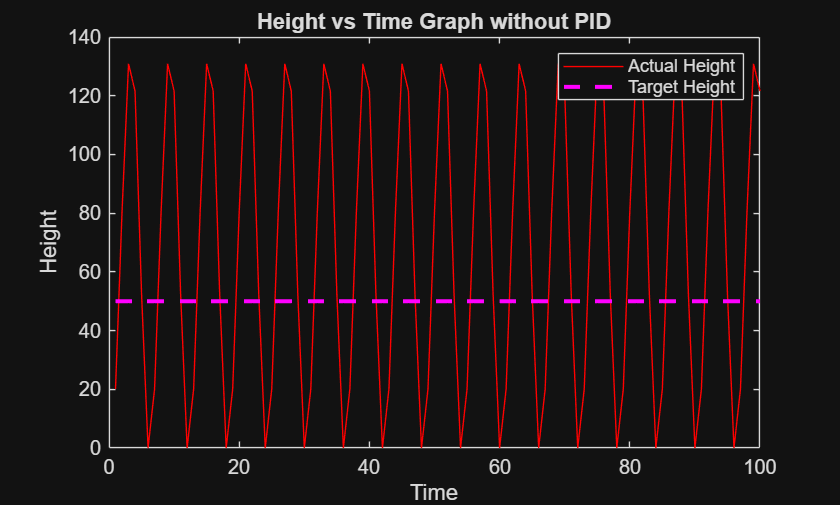

wantedPos = 50;
posCur = 0;
velCur = 0;
pos = zeros(1,100);
error = zeros(1,100);
timesteps = 1:100;
for time = 1:100

    if posCur < wantedPos
        accel = 50;
    else
        accel = -50;
    end
    [posCur,velCur] = phySim(accel,posCur,velCur);
    if posCur <=0
        posCur = 0; % Reset position if it goes below zero
        velCur = 0; % Reset velocity if position is zero
    end
    pos(1,time) = posCur;
    error(1,time) = wantedPos - posCur;
end

plot(timesteps,pos,'r-')
hold on
plot(timesteps,ones(1,100)*50,"magenta--",LineWidth=2)
title("Height vs Time Graph without PID")
xlabel("Time")
ylabel("Height")
legend("Actual Height","Target Height")
hold off

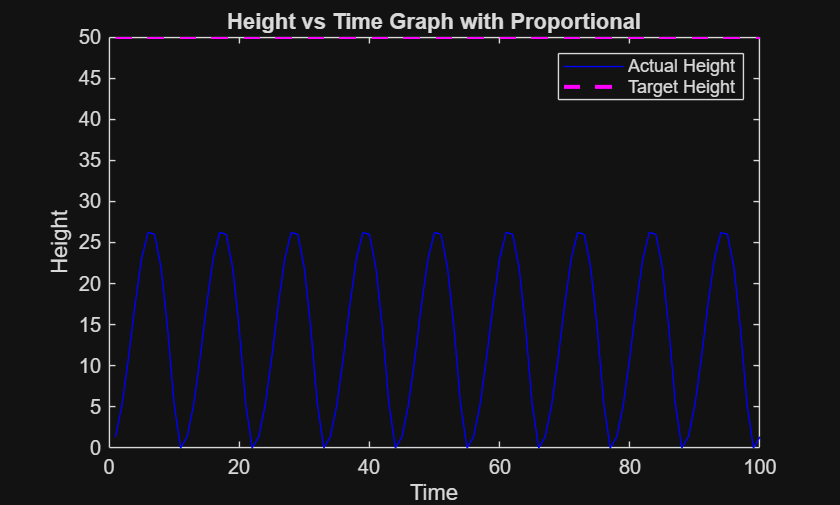


clear

wantedPos = 50;
posCur = 0;
velCur = 0;
pos = zeros(1,100);
timesteps = 1:100;
for time = 1:100

    accel = (wantedPos-posCur)*.25;

    [posCur,velCur] = phySim(accel,posCur,velCur);
    if posCur <=0
        posCur = 0; % Reset position if it goes below zero
        velCur = 0; % Reset velocity if position is zero
    end
    pos(1,time) = posCur;
    error(1,time) = wantedPos - posCur;
end

plot(timesteps,pos,'b-')
hold on
plot(timesteps,ones(1,100)*50,"magenta--",LineWidth=2)
title("Height vs Time Graph with Proportional")
xlabel("Time")
ylabel("Height")
legend("Actual Height","Target Height")
hold off

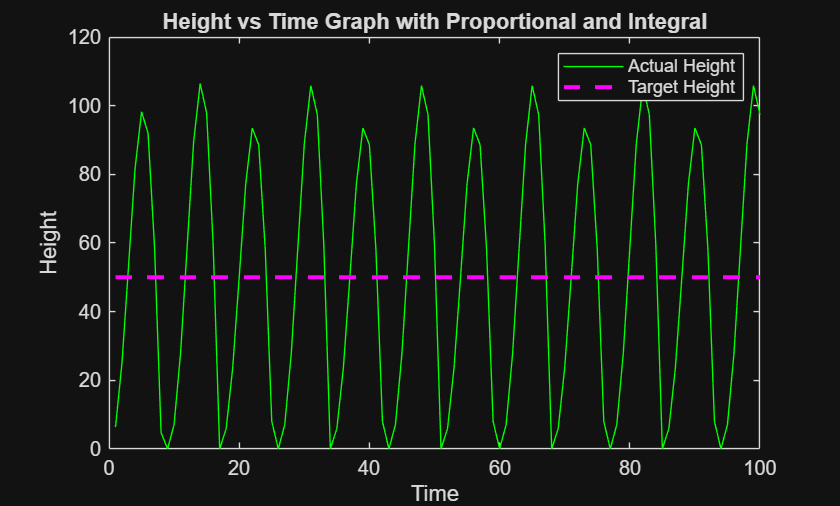


clear


wantedPos = 50;
posCur = 0;
velCur = 0;
pos = zeros(1,100);
timesteps = 1:100;
integ = 0;
for time = 1:100

    integ = integ + (wantedPos-posCur);
    accel = (wantedPos-posCur)*.4+integ*0.05;

    [posCur,velCur] = phySim(accel,posCur,velCur);
    if posCur <=0
        posCur = 0; % Reset position if it goes below zero
        velCur = 0; % Reset velocity if position is zero
    end
    pos(1,time) = posCur;
    error(1,time) = wantedPos - posCur;

end

plot(timesteps,pos,'g-')
hold on
plot(timesteps,ones(1,100)*50,"magenta--",LineWidth=2)
title("Height vs Time Graph with Proportional and Integral")
xlabel("Time")
ylabel("Height")
legend("Actual Height","Target Height")
hold off

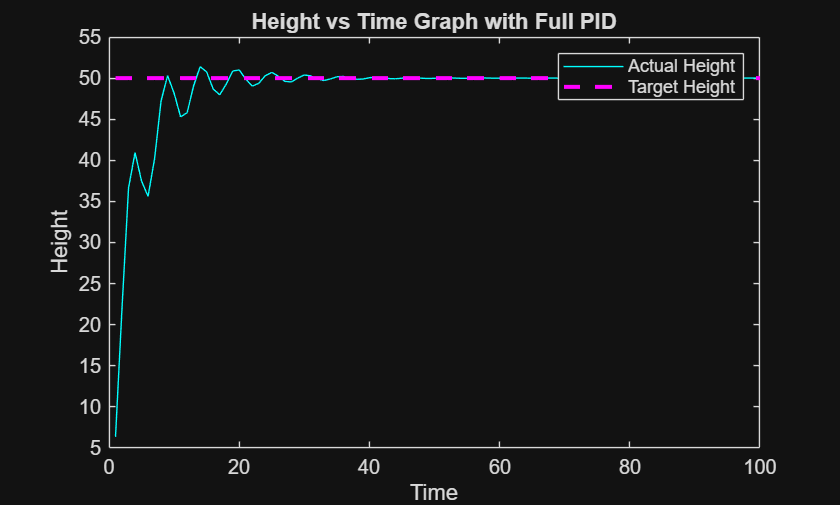


clear


wantedPos = 50;
posCur = 0;
velCur = 0;
accel = 0;
pos = zeros(1,100);
timesteps = 1:100;
integ = 0;
posPrev = 0;
for time = 1:100

    integ = integ + (wantedPos-posCur);
    deriv = (wantedPos-posCur)-(wantedPos-posPrev);
    accel = ((wantedPos-posCur)*0.4)+(integ*0.05)+deriv;
    posPrev = posCur;

    [posCur,velCur] = phySim(accel,posCur,velCur);
    if posCur <=0
        posCur = 0; % Reset position if it goes below zero
        velCur = 0; % Reset velocity if position is zero
    end
    pos(1,time) = posCur;
    error(1,time) = wantedPos - posCur;
end

plot(timesteps,pos,'cyan-')
hold on
plot(timesteps,ones(1,100)*50,"magenta--",LineWidth=2)
title("Height vs Time Graph with Full PID")
xlabel("Time")
ylabel("Height")
legend("Actual Height","Target Height")
hold off